clc
clear all
close all
pause('off')

# Assignment 3

# Japnit Sethi

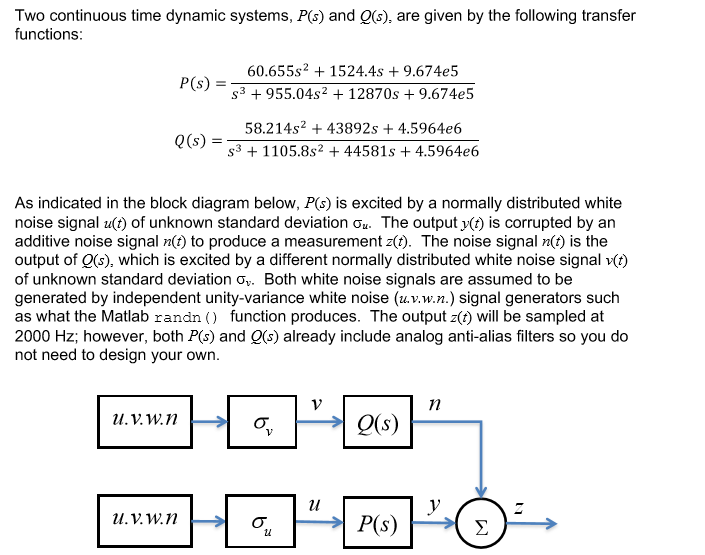

## **Solution**

We need to find standard deviation of v(t) {$\sigma_v$} given standard deviation of z(t) {$\sigma_z$}

**Note**: If for example we feed in noise v with standard deviation ${\sigma_v }^{\ast }$ = 1, we get a signal output with variance k, after that we just scale ${\sigma_v }^{\ast }$ by $\sigma_z$/k to get $\sigma_v$

This is based on the assumption that the noise standard deviation scales with magnitude as it is fed through the transfer function Q

% To actually find the magnitude of noise from phi_z to phi_v, we can
% assume the noise standard dev scales with magnitude as we feed it
% through the transfer function Q. If we feed noise v in with standard
% deviation phi_v_star = 1, and get a signal output with variance k, 
% then the we just need to scale phi_v_star by phi_z/k to get phi_v.

fs = 2000;     ts = 1/fs;

% Defining the Plant Filter
nump = [0, 60.655, 1524.4, 9.674e+05];
denp = [1, 955.04, 12870, 9.674e+05];
P = tf(nump, denp);

% Defining the Noise Filter
numq = [0, 58.214, 43892, 4.5964e+06];
denq = [1, 1105.8, 44571, 4.5964e+06];
Q = tf(numq, denq);

Sn_measured = 12;         % measured: Sv = Sn

N = 2^22;
t = ts * [0:N-1];

Sv_guess = 1;           % Initial guess
v = Sv_guess * randn(1, N);
Sv_check = std(v)

Sv_check = 1.0004


n = lsim(Q, v, t);          % generate noise sequence
Sn_estimated = std(n)       % actual

Sn_estimated = 0.1926


Sv_estimated = Sn_measured / Sn_estimated    % Estimated Standard Deviation v

Sv_estimated = 62.3171

v = Sv_estimated * randn(1, N);
Sv_check = std(v)

Sv_check = 62.3284


n = lsim(Q, v, t);          % generate noise sequence
Sn_estimated = std(n);      % actual
Sn_measured

Sn_measured = 12

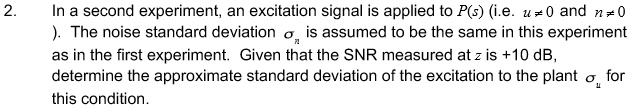

## **Solution**

Signal-to-noise ratio (SNR) = +10dB $\Longrightarrow$ 20*${\mathrm{log}}_{10} \left(x\right)=10\;$$\Longrightarrow$3.16228

Noise standard deviation $\sigma_n$ = 12

Magnitude of Signal output y = 3.16228*12 = 37.947

Now with knowledge of standard deviation of y, we can find:

$\sigma_u$ = ?

% Problem 2

SNR_desired = 10;    % dB

Sy_desired = Sn_measured * 10^(SNR_desired/20)

Sy_desired = 37.9473


Su_guess = 1       % initial guess

Su_guess = 1

u = Su_guess *  randn(1, N);

y = lsim(P, u, t);
Sy_estimated = std(y)                 % actual

Sy_estimated = 0.1359


Su_guess = Sy_desired / Sy_estimated    % actual % Required Answer

Su_guess = 279.1591

u = Su_guess *  randn(1, N);

y = lsim(P, u, t);
Sy_estimated = std(y) 

Sy_estimated = 38.2195


SNR_actual = 20*log10(Sy_estimated / Sn_measured) 

SNR_actual = 10.0621

SNR_desired

SNR_desired = 10


$$\textrm{abs}\left(\frac{\textrm{fft}\left(n\right)}{\sqrt{\textrm{Length}\;\textrm{of}\;\textrm{Signal}\;n}}\right)$$


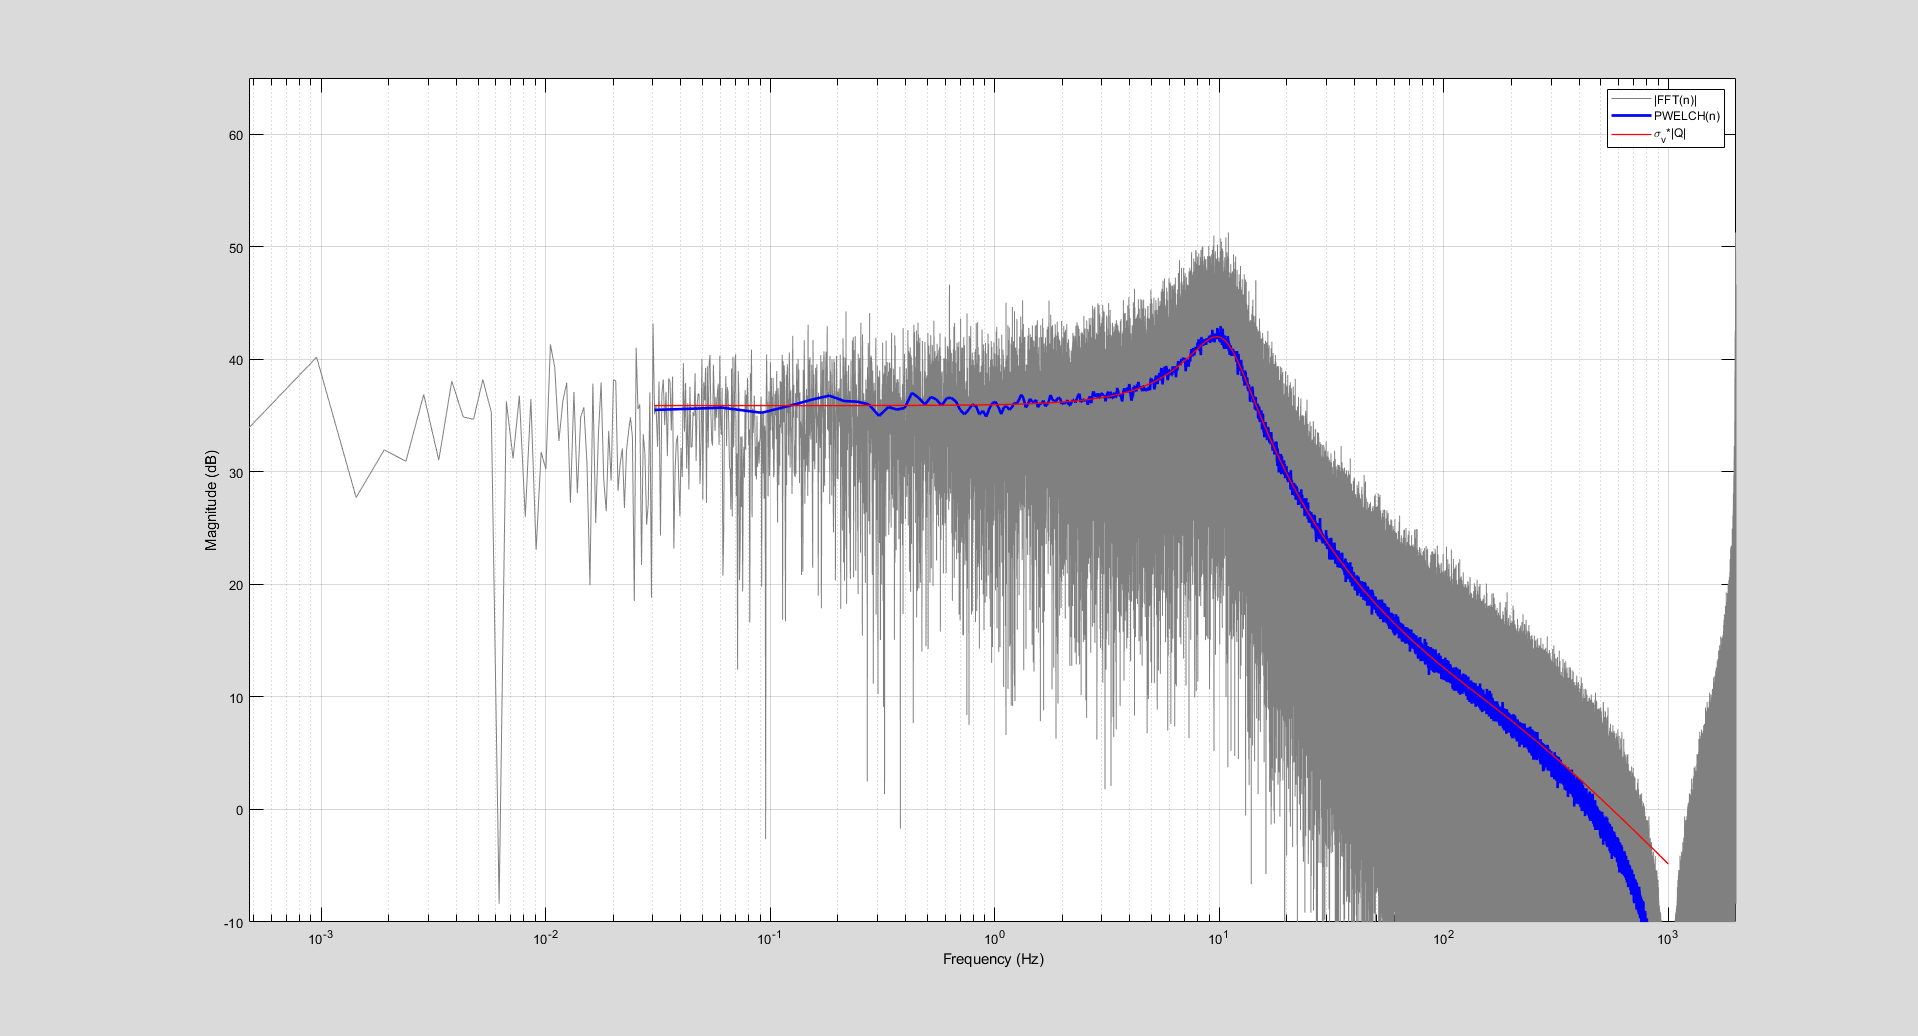

% Problem 3
 
NOISE_FFT = fft(n) / sqrt(N); % complex

F = fs/N;
fr1 = F * [0:N-1]; 

nfft = 2^16;  % tuning parameter
wndo = nfft;
ovlp = nfft/2;

% fr2 is 0 to fs/2
% NOISE_PWELCH is Power spectral density
[NOISE_PWELCH, fr2] = pwelch(n, wndo, ovlp, nfft, fs); 

NOISE_PWELCH = NOISE_PWELCH * (fs/2);

Q_MAG = Sv_estimated * squeeze(freqresp(Q, 2*pi*fr2));

figure()
whitebg(gcf, 'w');
subplot(1,1,1);
semilogx(fr1, 20*log10(abs(NOISE_FFT)), 'color', 0.5*[1 1 1])
grid on
hold on
semilogx(fr2, 10*log10(abs(NOISE_PWELCH)), 'b', 'linewidth', 2)
semilogx(fr2, 20*log10(abs(Q_MAG)), 'r', 'linewidth', 1)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
xlim([fr1(2), max(fr1)])
ylim([-10, 65])
legend('|FFT(n)|', 'PWELCH(n)', '\sigma_v*|Q|')

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

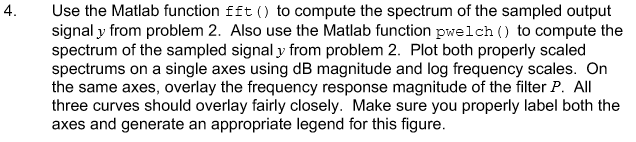

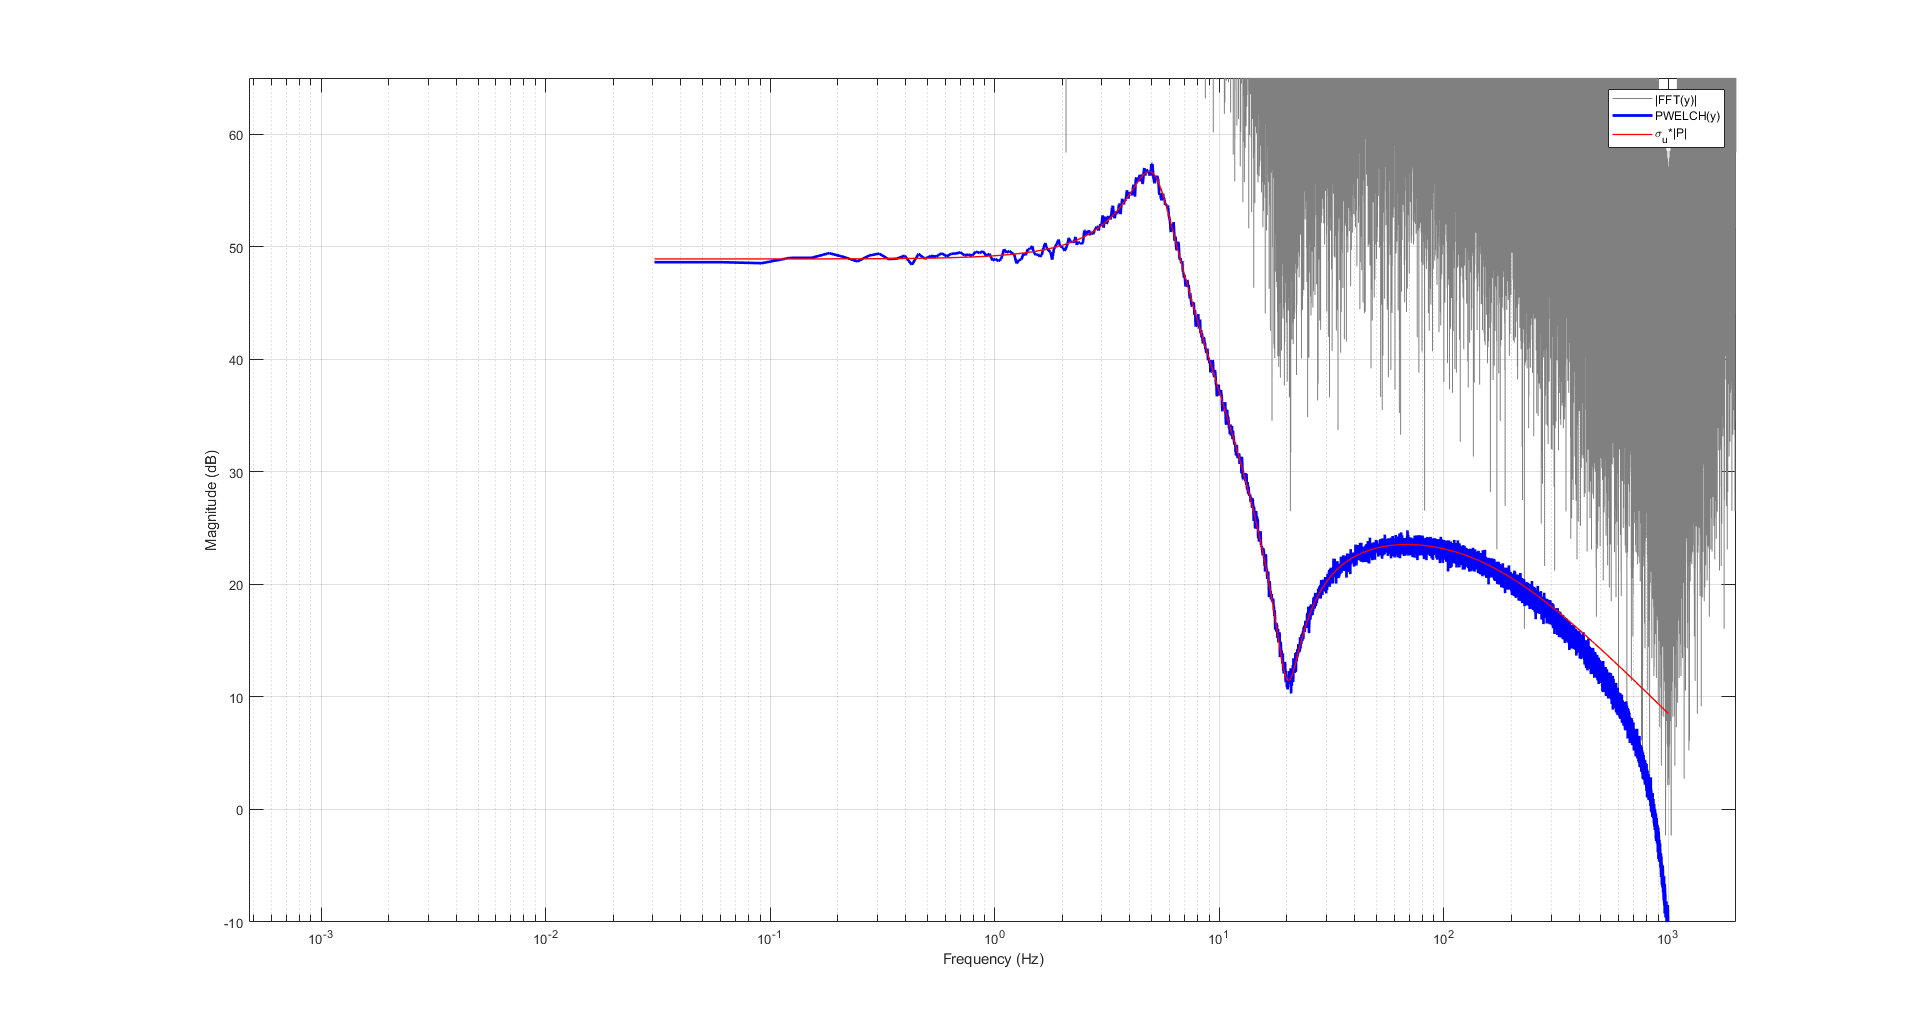

% Problem 4

Y_FFT = fft(y) / sqrt(N);

[Y_PWELCH, fr2] = pwelch(y, wndo, ovlp, nfft, fs);

Y_PWELCH = Y_PWELCH * (fs/2);

P_MAG = Su_guess * squeeze(freqresp(P, 2*pi*fr2));

figure()
subplot(1,1,1);
semilogx(fr1, 20*log10(abs(Y_FFT)), 'color', 0.5*[1 1 1])
grid on
hold on
semilogx(fr2, 10*log10(abs(Y_PWELCH)), 'b', 'linewidth', 2)
semilogx(fr2, 20*log10(abs(P_MAG)), 'r', 'linewidth', 1)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
xlim([fr1(2), max(fr1)])
ylim([-10, 65])
legend('|FFT(y)|', 'PWELCH(y)', '\sigma_u*|P|')

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

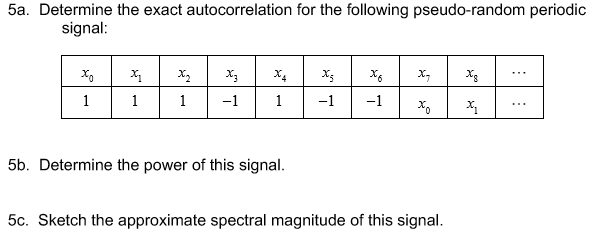

## **Solution:**

**5a)**

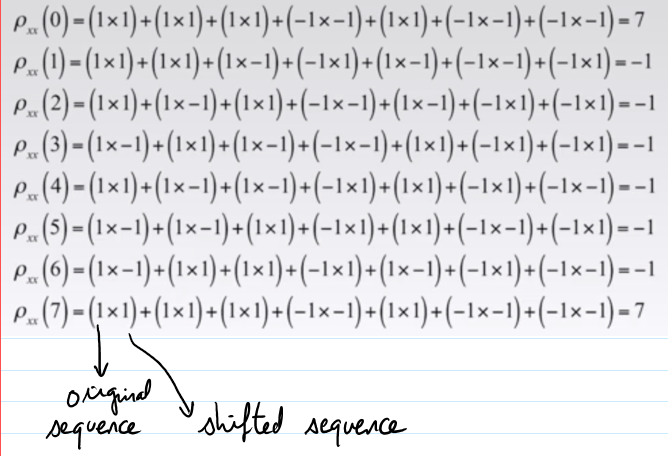

#### **5b)**  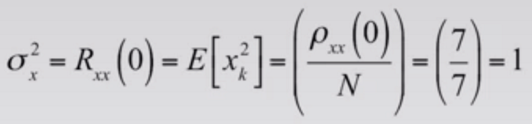

### **5c) **

% Problem 5

% Part_A
xk = [1 1 1 -1 1 -1 -1];
N = 7;

col = xk';
row = [xk(end), xk(1:end-1)];

Y = hankel(col, row)

Y =      1     1     1    -1     1    -1    -1
     1     1    -1     1    -1    -1     1
     1    -1     1    -1    -1     1     1
    -1     1    -1    -1     1     1     1
     1    -1    -1     1     1     1    -1
    -1    -1     1     1     1    -1     1
    -1     1     1     1    -1     1    -1



Rxy = (1/N) * Y * xk'

Rxy =     1.0000
   -0.1429
   -0.1429
   -0.1429
   -0.1429
   -0.1429
   -0.1429



% Part C

W = exp(-1i*2*pi/N)

W = 0.6235 - 0.7818i


for m = 1:N
    X(m) = 0;
    for n = 1:N
        X(m) = X(m) + xk(n)*W^((m-1)*(n-1));
    end
end
abs(X)

ans =     1.0000    2.8284    2.8284    2.8284    2.8284    2.8284    2.8284
